## Heart rate 

### Tasks

1. Measure the transient change in heart rate (TF) in response to a reduction in your body's ongoing physical activity. The initial state is the heart rate during increased physical exertion, then you enter a state of rest when you record a transient event (TF). Follow the teacher's instructions.

2. Create a dynamic model of the above event. Choose the structure of the model and the method of identification appropriately. Compare the measured TF with the model response.

#### Initialize

clc; clear all; addpath('..')

### 1. Load data

load("heart_rate.mat")

### 2. Preprocess data

#### Sampling time

Ts = 10/60; % [min]
t_original = (0:length(heart_rate)-1)*Ts;

#### Resampling

Ts = 0.01;
t = 0:Ts:t_original(end);
heart_rate = interp1(t_original,heart_rate,t);

#### Create input

u = [1 zeros(1,length(heart_rate)-1)];

#### Normalize data

heart_rate = (heart_rate-heart_rate(1));
u = (u-u(1));

#### Plot data

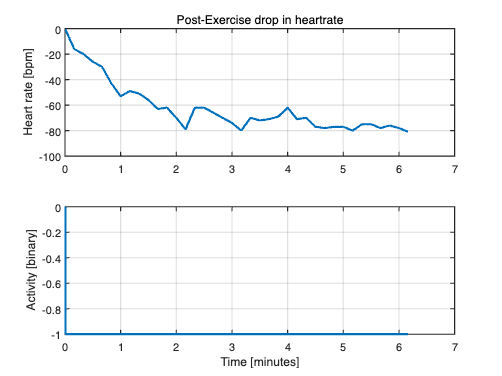

subplot(2,1,1)
plot(t, heart_rate, 'LineWidth', 2)
grid on
ylabel('Heart rate [bpm]')
title('Post-Exercise drop in heartrate', 'FontWeight','Normal')
subplot(2,1,2)
stairs(t, u, 'LineWidth', 2)
grid on
xlabel('Time [minutes]')
ylabel('Activity [binary]')

### 3. Identify system 

Given specified order 

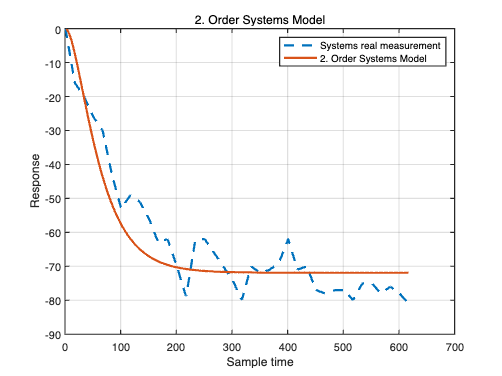

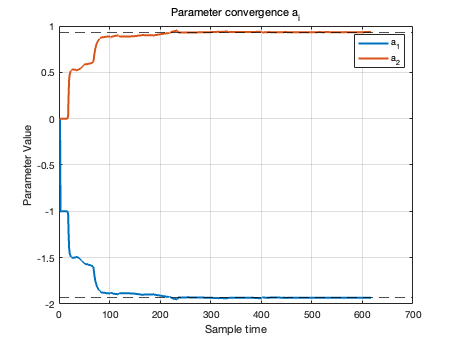

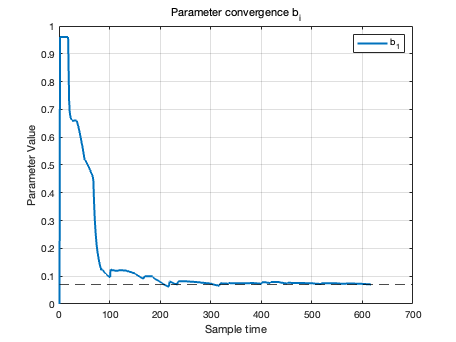

num_order = 1;
den_order = 2;
idtf = recursiveLeastSquares(u, heart_rate, Ts, ...
                             num_order, den_order);

idtf.Structure

ans =
 
            0.07033
  ----------------------------
  1 - 1.934 z^-1 + 0.9347 z^-2
 
Sample time: 0.01 seconds
Discrete-time transfer function.




% Time constants
[w, zeta, p] = damp(idtf.Structure);
T = 1./w 

T =     0.4464
    0.2214
